%%% Plots 3 subplots with r, \dot{r} and \dot{fi} in vs. time. Uses 
%%% results of X_Dock_time. Can be scaled or not. Typ - docking process 
%%% type, skal - skalowanie. Newer, better version of .m file.

clear
close all
clc
delete(gcp('nocreate'))
tic


## load data and functions


DIR ='/home/pracownicy/karpinska/Dokumenty/Praca_doktorska_analizy/Monodisperse_particles/';
spec='Results_dock_time/Initial_vel_fluid/';
loadDIR=[DIR spec];

% Declare constants, load functions and data
Const = Constants;
fDIR='/home/pracownicy/karpinska/Dokumenty/Praca_doktorska_analizy/Monodisperse_particles/Functions/';
addpath(fDIR)

load([loadDIR 'Dock_time_eps_00001_inorbit_katy.mat'])


## choose plot parameters


% choose plot type
typ=0;  % 0- z eps do r_orb
        % 1- z r_s do eps,
%
fsize=16;
width=20;
height=25;

%skalowanie: 0- nie, 1- tak
skal=0;

% co_ile shows how many lines in a group we want
ile=5;

powiel_min=5;

## data manipulation


switch typ
    case 1
        r0=1.58499;
    case 0
        r0=0;
end

% choose relevant St/A values (for respective docking process)
wybor=[];
param=zeros(1,numel(part));
for p=1:numel(part)
    param(p)=part(p).par.A^(-1)*part(p).par.St;
    if abs(part(p).init.r0_bez-r0)<=eps && imag(texit(p))==0 && ~isnan(texit(p))
        wybor=[wybor,p];
    end
end

param_wyb=param(wybor);
parmin=min(param_wyb);
parmax=max(param_wyb);
St_wyb=St(wybor);
A_wyb=A(wybor);
% group
%choose grouping parameter
P_wyb=round(St_wyb./A_wyb);
%find groups of the same par. value
[P_id,Pgr]=findgroups(P_wyb);
for k=1:numel(Pgr)
    ids{k}=find(P_id==k);
    ids_nr(k)=numel(ids{k});
end
najliczniejsze=nonzeros((ids_nr>=powiel_min).*(1:numel(Pgr)));

% generate colors for each St/A
switch typ
    case 1
        col_basic=hsv(numel(najliczniejsze));
    case 0
        col_basic=jet(numel(najliczniejsze));
end



## plot

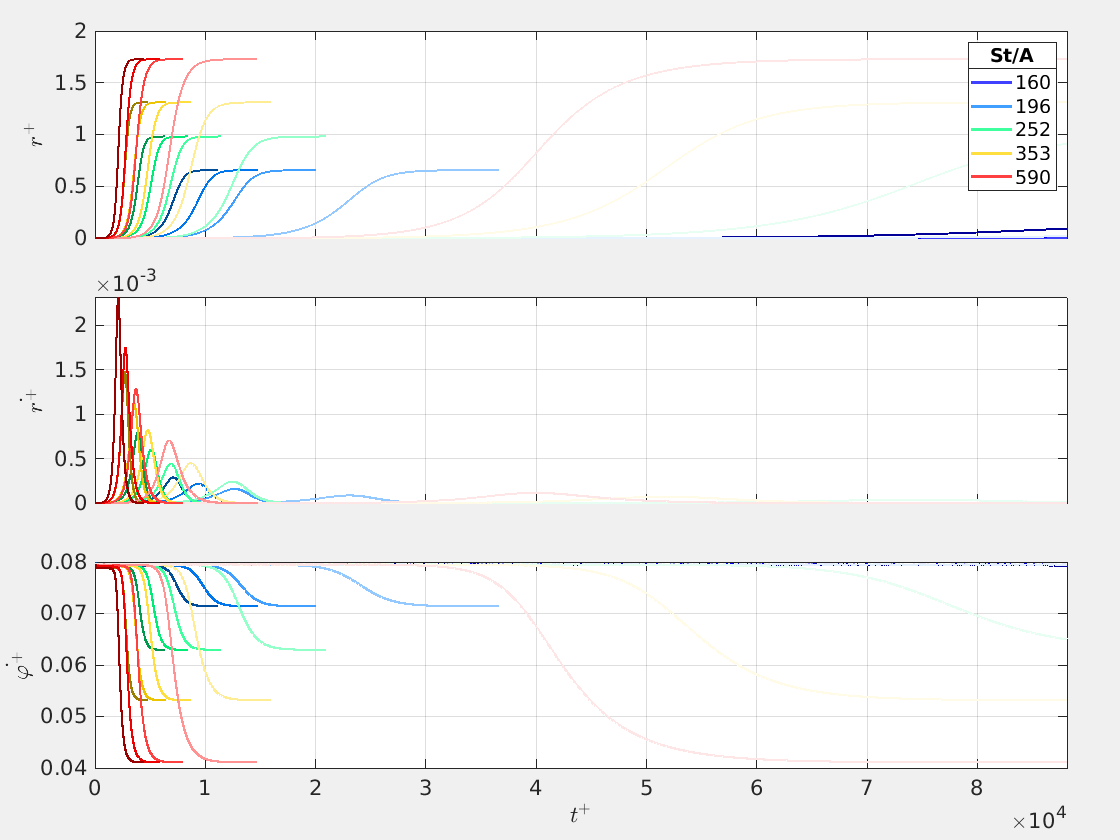


figure
set(gcf,'Visible','on')
set(gcf,'Position', [640, 300, 2*560, 2*420 ],...
    'paperunits','centimeters',...
    'papersize',[width,height],...
    'InvertHardCopy','off')
 set(gca,'FontSize',fsize)
 rysunek=tiledlayout(3, 1,'Padding','compact');
 leg={};
 subsecik=[];
 
for p=1:5:numel(najliczniejsze)
    
    k=najliczniejsze(p);
    par_temp=Pgr(k);
    leg{numel(leg)+1}=num2str(par_temp);
    numerki_all=wybor(ids{k});
    
    numerki=numerki_all(round(linspace(1,numel(numerki_all),ile)));
    param_wyb=param(wybor);
    maxt=max(texit(numerki));
    Plot_docking_trajectory
end
legenda=legend(subsecik,leg);
title(legenda,'St/A')